# Kalman Consensus Filter

## Setup

format short;
del_t = 1; % time step
itr = 100; % total time steps
random_acc_sd = 0.2;

% Sensor noise
sens1_sd = 0.5; % 1.17
sens2_sd = 1.0; % 1.0
sens3_sd = 1.5; % 1.5
sens4_sd = 2.0; % 1.3
sensor_noise = [0,0,0,0;sens1_sd,sens2_sd,sens3_sd,sens4_sd];

N = 4; % # sensors
eps = 0.1; % Consensus term

% Initial guess
init_x = [0 0 0 0 0 0]';
init_p = [500 0 0 0 0 0;
          0 500 0 0 0 0;
          0 0 500 0 0 0;
          0 0 0 500 0 0;
          0 0 0 0 500 0;
          0 0 0 0 0 500];

% State transistion model
f = [1 del_t 0.5*power(del_t,2) 0 0 0;
     0 1 del_t 0 0 0;
     0 0 1 0 0 0;
     0 0 0 1 del_t 0.5*power(del_t,2);
     0 0 0 0 1 del_t;
     0 0 0 0 0 1];

% Process noise
q = [power(del_t,4)/4 power(del_t,3)/2 power(del_t,2)/2 0 0 0;
     power(del_t,3)/2 power(del_t,2)/2 del_t 0 0 0;
     power(del_t,2)/2 del_t 1 0 0 0;
     0 0 0 power(del_t,4)/4 power(del_t,3)/2 power(del_t,2)/2;
     0 0 0 power(del_t,3)/2 power(del_t,2)/2 del_t;
     0 0 0 power(del_t,2)/2 del_t 1];
q = q * power(random_acc_sd,2);

% Measurement model
h_1 = [1 0 0 0 0 0; % TODO: Separate H for each sensors
     0 0 0 1 0 0];
h_2 = [1 0 0 0 0 0; % TODO: Separate H for each sensors
     0 0 0 1 0 0];


% Mesurement noise
R = NaN(2,2,N);
R(:,:,1) = [power(sensor_noise(2,1),2) 0;
      0 power(sensor_noise(2,1),2)];
R(:,:,2) = [power(sensor_noise(2,2),2) 0;
      0 power(sensor_noise(2,2),2)];
R(:,:,3) = [power(sensor_noise(2,3),2) 0;
      0 power(sensor_noise(2,3),2)];
R(:,:,4) = [power(sensor_noise(2,4),2) 0;
      0 power(sensor_noise(2,4),2)];

## Generate sensor values

%==================================================
% To generate sensor data for the first time
%==================================================

% radius = 5;
% start_x = 0;
% start_y = 0;
% [true_x,true_y] = gen_true_val(start_x,start_y,radius);
% 
% data_struct.id = 1;
% data_struct.start_x = start_x;
% data_struct.start_y = start_y;
% data_struct.radius = radius;
% data_struct.true_x = true_x;
% data_struct.true_y = true_y;
% 
% z0 = gen_sens_val(true_x,true_y,0.5); % TODO: needs to come from the benchmark from paper
% z1 = gen_sens_val(true_x,true_y,sensor_noise(2,1));
% z2 = gen_sens_val(true_x,true_y,sensor_noise(2,2));
% z3 = gen_sens_val(true_x,true_y,sensor_noise(2,3));
% z4 = gen_sens_val(true_x,true_y,sensor_noise(2,4));
% 
% data_struct.sensor1.x = z1(1,:);
% data_struct.sensor1.y = z1(2,:);
% 
% data_struct.sensor2.x = z2(1,:);
% data_struct.sensor2.y = z2(2,:);
% 
% data_struct.sensor3.x = z3(1,:);
% data_struct.sensor3.y = z3(2,:);
% 
% data_struct.sensor4.x = z4(1,:);
% data_struct.sensor4.y = z4(2,:);
% 
% save("data.mat","data_struct");
%--------------------------------------------------

%==================================================
% To load data from data.mat
%==================================================

data = load("data.mat");

% load ground truth
true_x = data.data_struct.true_x(1:itr);
true_y = data.data_struct.true_y(1:itr);

% load sensor data
Z = zeros(2,4,itr);
Z(1,1,:) = data.data_struct.sensor1.x(1:itr);
Z(2,1,:) = data.data_struct.sensor1.y(1:itr);
Z(1,2,:) = data.data_struct.sensor2.x(1:itr);
Z(2,2,:) = data.data_struct.sensor2.y(1:itr);
Z(1,3,:) = data.data_struct.sensor3.x(1:itr);
Z(2,3,:) = data.data_struct.sensor3.y(1:itr);
Z(1,4,:) = data.data_struct.sensor4.x(1:itr);
Z(2,4,:) = data.data_struct.sensor4.y(1:itr);

## Initialization

% Prediction Step
x_1 = f*init_x;
p_1 = f*init_p*f' + q;

% Network connection
J = [ 1 2 4; 2 3 1; 3 4 2; 4 1 3];

% Storage initialization
X_Est = NaN(6,N,itr); % TODO: Create a variable to store the estimate from the best sensor
P_Est = NaN(6,6,N,itr);

X_Pred = NaN(6,N,itr+1);
P_Pred = NaN(6,6,N,itr+1);

M_I = NaN(6,6,N,itr);
Final_Est = NaN(2,itr);

con_diff = NaN(2,N,itr);

X_Pred(:,1,1) = x_1;
X_Pred(:,2,1) = x_1;
X_Pred(:,3,1) = x_1;
X_Pred(:,4,1) = x_1;

P_Pred(:,:,1,1) = p_1;
P_Pred(:,:,2,1) = p_1;
P_Pred(:,:,3,1) = p_1;
P_Pred(:,:,4,1) = p_1;

## Algorithm

for i = 1:itr
    % At each iterations
    for n = 1:4
        % for every sensor
        msg.y_n = zeros(6,N-1); % measurement % N-1 because each sensor can have two neighboring sensor + itself
        msg.s_n = zeros(6,6,N-1); % covariance
        msg.x_n = zeros(2,N-1); % state estimate
        for nei = 1:N-1
            % for every neighbour
            j = J(n,nei);
            r_nei = R(:,:,j);
            z_nei = Z(:,j,i);
            msg.y_i(:,nei) = h'*inv(r_nei)*z_nei;
            msg.s_i(:,:,nei) = h'*inv(r_nei)*h;
            msg.x_i(:,nei) = [X_Pred(1,j,i);X_Pred(4,j,i)];
        end

        % current state estimate
        y_i = zeros(6,1);
        s_i = zeros(6,6);
        x_diff_sum = 0;
        for m = 1:N-1
            y_i = y_i + msg.y_i(:,m);
            s_i = s_i + msg.s_i(:,:,m);
            if m ~= 1
                x_diff_sum = x_diff_sum + (msg.x_i(:,m) - msg.x_i(:,1));
            end
        end
        con_diff(1,n,i) = x_diff_sum(1,1);
        con_diff(2,n,i) = x_diff_sum(2,1);
        x_diff_sum = [x_diff_sum(1,1) 0 0 x_diff_sum(2,1) 0 0]';

        M_i = inv(inv(P_Pred(:,:,n,i)) + s_i);
        M_I(:,:,n,i) = M_i;
        x_p = X_Pred(:,n,i);
        innov = y_i - (s_i*x_p);
        x_est = x_p + (M_i*innov) + (eps*M_i*x_diff_sum);

        % Update state
        p_next = f*M_i*f' + q;
        x_next = f*x_est;

        % Store values
        X_Est(:,n,i) = x_est;
        X_Pred(:,n,i+1) = x_next;
        P_Pred(:,:,n,i+1) = p_next;
    end
    smallest_i = 0;
    smallest_val = inf;
    for l = 1:N
        if M_I(1,1,N,i) < smallest_val
            smallest_val = M_I(1,1,N,i);
            smallest_i = l;
        end
    end
    Final_Est(:,i) = [X_Est(1,l,i);X_Est(4,l,i)];
end

## Error Calculation

% Individual points error
summ = 0;
for c = 1:itr
    sqr_error = (Final_Est(1,c) - true_x(1,c))^2 + (Final_Est(2,c) - true_y(1,c))^2;
    summ = summ + sqr_error;
end
MSE = summ / itr;

## Visualization

%==================================================
% Visulaize ground truth and senor mesurements
%==================================================
Show = false;

if Show
    figure;
    draw_trajectory(true_x,true_y,'g');
    hold on;
    draw_trajectory(reshape(Z(1,1,:),[1,itr]),reshape(Z(2,1,:),[1,itr]),'r');
    draw_trajectory(reshape(Z(1,2,:),[1,itr]),reshape(Z(2,2,:),[1,itr]),'k');
    draw_trajectory(reshape(Z(1,3,:),[1,itr]),reshape(Z(2,3,:),[1,itr]),'b');
    draw_trajectory(reshape(Z(1,4,:),[1,itr]),reshape(Z(2,4,:),[1,itr]),'m');
    legend(["Ground Truth", "Sensor 1", "Sensor 2", "Sensor 3", "Sensor 4"]);
    title("Ground Truth vs Sensor Measurements");
end

disp(MSE);

    0.1047



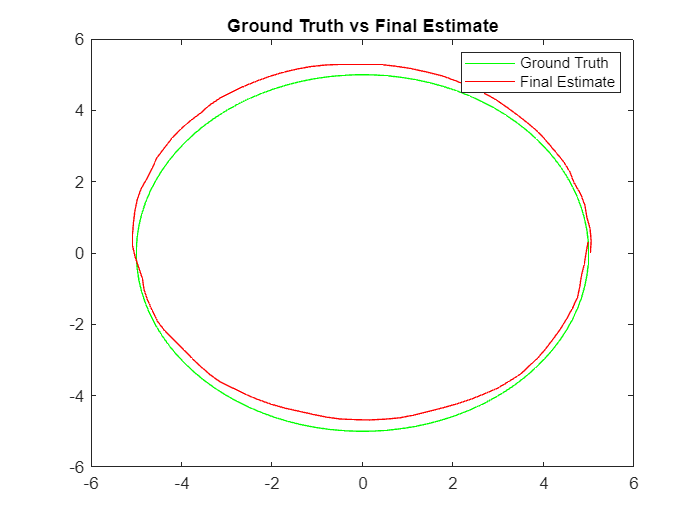


figure;
draw_trajectory(true_x,true_y,'g');
hold on;
plot(Final_Est(1,:),Final_Est(2,:),'r');
legend(["Ground Truth", "Final Estimate"]);
title("Ground Truth vs Final Estimate")


% axis([-7 7 -7 7])

%==================================================
% Visulaize node estimates
%==================================================
start_itr = 1;
end_itr = 100;
total_itr = (end_itr-start_itr)+1;
Show = false;

if Show
    figure;
    tcl = tiledlayout(2,2);
    tcl.Title.String = "Ground Truth vs Node Estimates";
    
    % Node 1
    nexttile(tcl);
    % subplot(2,2,1);
    hold on;
    grid on;
    truth = plot(true_x(1,start_itr:end_itr),true_y(1,start_itr:end_itr),"g","DisplayName","Ground Truth");
    n1 = plot(reshape(X_Est(1,1,start_itr:end_itr),[1,total_itr]),reshape(X_Est(4,1,start_itr:end_itr),[1,total_itr]),"r","DisplayName","Node 1");
    % n22 = plot(reshape(X_Est(1,2,start_itr:end_itr),[1,total_itr]), reshape(X_Est(4,2,start_itr:end_itr),[1,total_itr]),"b","DisplayName","Node 2");
    % n44 = plot(reshape(X_Est(1,4,start_itr:end_itr),[1,total_itr]), reshape(X_Est(4,4,start_itr:end_itr),[1,total_itr]),"m","DisplayName","Node 4");
    % axis([-7 7 -7 7])
    
    % Node 2
    nexttile(tcl);
    % subplot(2,2,2);
    hold on;
    grid on;
    plot(true_x(1,start_itr:end_itr),true_y(1,start_itr:end_itr),"g");
    n2 = plot(reshape(X_Est(1,2,start_itr:end_itr),[1,total_itr]), reshape(X_Est(4,2,start_itr:end_itr),[1,total_itr]),"k","DisplayName","Node 2");
    % axis([-7 7 -7 7])
    
    % Node 3
    nexttile(tcl);
    % subplot(2,2,3);
    hold on;
    grid on;
    plot(true_x(1,start_itr:end_itr),true_y(1,start_itr:end_itr),"g");
    n3 = plot(reshape(X_Est(1,3,start_itr:end_itr),[1,total_itr]), reshape(X_Est(4,3,start_itr:end_itr),[1,total_itr]),"b","DisplayName","Node 3");
    % axis([-7 7 -7 7])
    
    % Node 4
    nexttile(tcl);
    % subplot(2,2,4);
    hold on;
    grid on;
    plot(true_x(1,start_itr:end_itr),true_y(1,start_itr:end_itr),"g");
    n4 = plot(reshape(X_Est(1,4,start_itr:end_itr),[1,total_itr]), reshape(X_Est(4,4,start_itr:end_itr),[1,total_itr]),"m","DisplayName","Node 4");
    % axis([-7 7 -7 7])
    
    hL = legend([truth,n1,n2,n3,n4]);
    hL.Layout.Tile = 'East';
end

%==================================================
% Consensus Chart
%==================================================
start_itr = 1;
end_itr = 100;
total_itr = (end_itr-start_itr)+1;
Show = false;

if Show
    figure;
    subplot(1,2,1);
    hold on;
    grid on;
    plot(reshape(con_diff(1,1,start_itr:end_itr),[1,total_itr]),'r');
    plot(reshape(con_diff(1,2,start_itr:end_itr),[1,total_itr]),'g');
    plot(reshape(con_diff(1,3,start_itr:end_itr),[1,total_itr]),'b');
    plot(reshape(con_diff(1,4,start_itr:end_itr),[1,total_itr]),'m');
    % axis([0 end_itr -1 1])
    
    subplot(1,2,2);
    hold on;
    grid on;
    plot(reshape(con_diff(2,1,start_itr:end_itr),[1,total_itr]),'r');
    plot(reshape(con_diff(2,2,start_itr:end_itr),[1,total_itr]),'g');
    plot(reshape(con_diff(2,3,start_itr:end_itr),[1,total_itr]),'b');
    plot(reshape(con_diff(2,4,start_itr:end_itr),[1,total_itr]),'m');
end


% axis([0 end_itr -1 1])

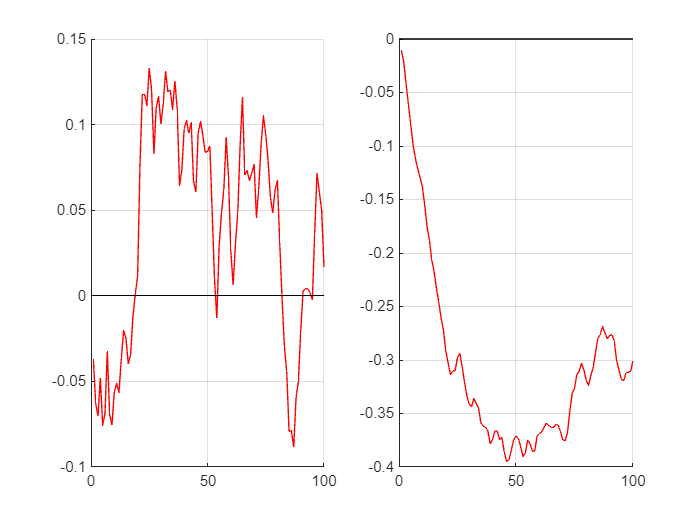

%==================================================
% Estimate Error
%==================================================
start_itr = 1;
end_itr = 100;
total_itr = (end_itr-start_itr)+1;
Show = false;

if Show
    figure;
    subplot(1,2,1);
    hold on;
    grid on;
    plot(true_x(1,start_itr:end_itr)-reshape(X_Est(1,1,start_itr:end_itr),[1,total_itr]), 'r');
    plot(true_x(1,start_itr:end_itr)-reshape(X_Est(1,2,start_itr:end_itr),[1,total_itr]), 'g');
    plot(true_x(1,start_itr:end_itr)-reshape(X_Est(1,3,start_itr:end_itr),[1,total_itr]), 'b');
    plot(true_x(1,start_itr:end_itr)-reshape(X_Est(1,4,start_itr:end_itr),[1,total_itr]), 'm');
    plot([0 100],[0 0],'k');
    % axis([0 end_itr -0.2 0.5])
    
    subplot(1,2,2);
    hold on;
    grid on;
    plot(true_y(1,start_itr:end_itr)-reshape(X_Est(4,1,start_itr:end_itr),[1,total_itr]),'r');
    plot(true_y(1,start_itr:end_itr)-reshape(X_Est(4,2,start_itr:end_itr),[1,total_itr]),'g');
    plot(true_y(1,start_itr:end_itr)-reshape(X_Est(4,3,start_itr:end_itr),[1,total_itr]),'b');
    plot(true_y(1,start_itr:end_itr)-reshape(X_Est(4,4,start_itr:end_itr),[1,total_itr]),'m');
    plot([0 100],[0 0],'k');
end

figure;
subplot(1,2,1);
hold on;
grid on;
plot(true_x - Final_Est(1,:), 'r');
plot([0 100],[0 0],'k');
% axis([0 end_itr -0.2 0.5])

subplot(1,2,2);
hold on;
grid on;
plot(true_y - Final_Est(2,:), 'r');
plot([0 100],[0 0],'k');


% axis([0 end_itr -0.6 0])

%==================================================
% Ground Truth vs Estimate Error
%==================================================
start_itr = 1;
end_itr = 10;
total_itr = (end_itr-start_itr)+1;
Show = false;

if Show
    figure;
    subplot(4,2,1);
    plot(true_x(1,start_itr:end_itr)-reshape(X_Est(1,1,start_itr:end_itr),[1,total_itr]));
    hold on;
    plot([0 100],[0 0],'r');
    subplot(4,2,2);
    plot(true_y(1,start_itr:end_itr)-reshape(X_Est(4,1,start_itr:end_itr),[1,total_itr]));
    hold on;
    plot([0 100],[0 0],'r');
    
    subplot(4,2,3);
    plot(true_x(1,start_itr:end_itr)-reshape(X_Est(1,2,start_itr:end_itr),[1,total_itr]));
    hold on;
    plot([0 100],[0 0],'r');
    subplot(4,2,4);
    plot(true_y(1,start_itr:end_itr)-reshape(X_Est(4,2,start_itr:end_itr),[1,total_itr]));
    hold on;
    plot([0 100],[0 0],'r');
    
    subplot(4,2,5);
    plot(true_x(1,start_itr:end_itr)-reshape(X_Est(1,3,start_itr:end_itr),[1,total_itr]));
    hold on;
    plot([0 100],[0 0],'r');
    subplot(4,2,6);
    plot(true_y(1,start_itr:end_itr)-reshape(X_Est(4,3,start_itr:end_itr),[1,total_itr]));
    hold on;
    plot([0 100],[0 0],'r');
    
    subplot(4,2,7);
    plot(true_x(1,start_itr:end_itr)-reshape(X_Est(1,4,start_itr:end_itr),[1,total_itr]));
    hold on;
    plot([0 100],[0 0],'r');
    subplot(4,2,8);
    plot(true_y(1,start_itr:end_itr)-reshape(X_Est(4,4,start_itr:end_itr),[1,total_itr]));
    hold on;
    plot([0 100],[0 0],'r');
end


## Functions

function [x,y] = gen_true_val(x,y,r)
    th = linspace(0,2*pi,itr);
    x = r * cos(th) + x;
    y = r * sin(th) + y;
end

function O = gen_sens_val(true_x,true_y,sd)
    N = length(true_x);
    noise_raw_x = randn(1,N)*sd;
    noise_raw_y = rand(1,N)*sd;
    window_size = 20;
    b = ones(window_size,1)/window_size;
    a = 1;
    noise_filtered_x = filter(b, a, noise_raw_x);
    noise_filtered_y = filter(b, a, noise_raw_y);
    sens_x = (true_x + noise_filtered_x);
    sens_y = (true_y + noise_filtered_y);
    O = [sens_x;sens_y];
end

function draw_trajectory(x,y,clr)
    plot(x,y,clr);
end